## Lumped modeling of heat transfer 

[Simscape](https://www.mathworks.com/products/simscape.html) allows the rapid creation of physical system models in the [Simulink](https://www.mathworks.com/products/simulink.html) environment. It facilitates the building of models based on physical component and direct physical connections, integrating with block diagrams and other modeling paradigms. [Simscape Fluid](https://www.mathworks.com/products/simscape-fluids.html) includes components to model thermal and fluidic systems. It contains fundamental parts and phenomena such as therm conduction and convection in a lumped mass and complex components such as heat exchangers and refrigeration cycles. 

 
editor = matlab.desktop.editor.getActive;
% Check if there is an open file
if ~isempty(editor)
    % Get the full path of the current open file
    currentFilePath = editor.Filename;
    
    % Extract the folder path from the full file path
    [currentFileFolder, ~, ~] = fileparts(currentFilePath);
    
    % Get the current working directory
    currentDir = pwd;
    
    % Check if the working directory is different from the file's folder
    if ~strcmp(currentDir, currentFileFolder)
        % Change the working directory to the file's folder
        cd(currentFileFolder);
        fprintf('Changed working directory to: %s\n', currentFileFolder);
    else
        fprintf('Already in the correct directory: %s\n', currentDir);
    end
else
    fprintf('No file is currently open in the MATLAB Editor.\n');
end

## A Simple Heat Transfer Example - Heat Conduction/Convection in an Iron Rod

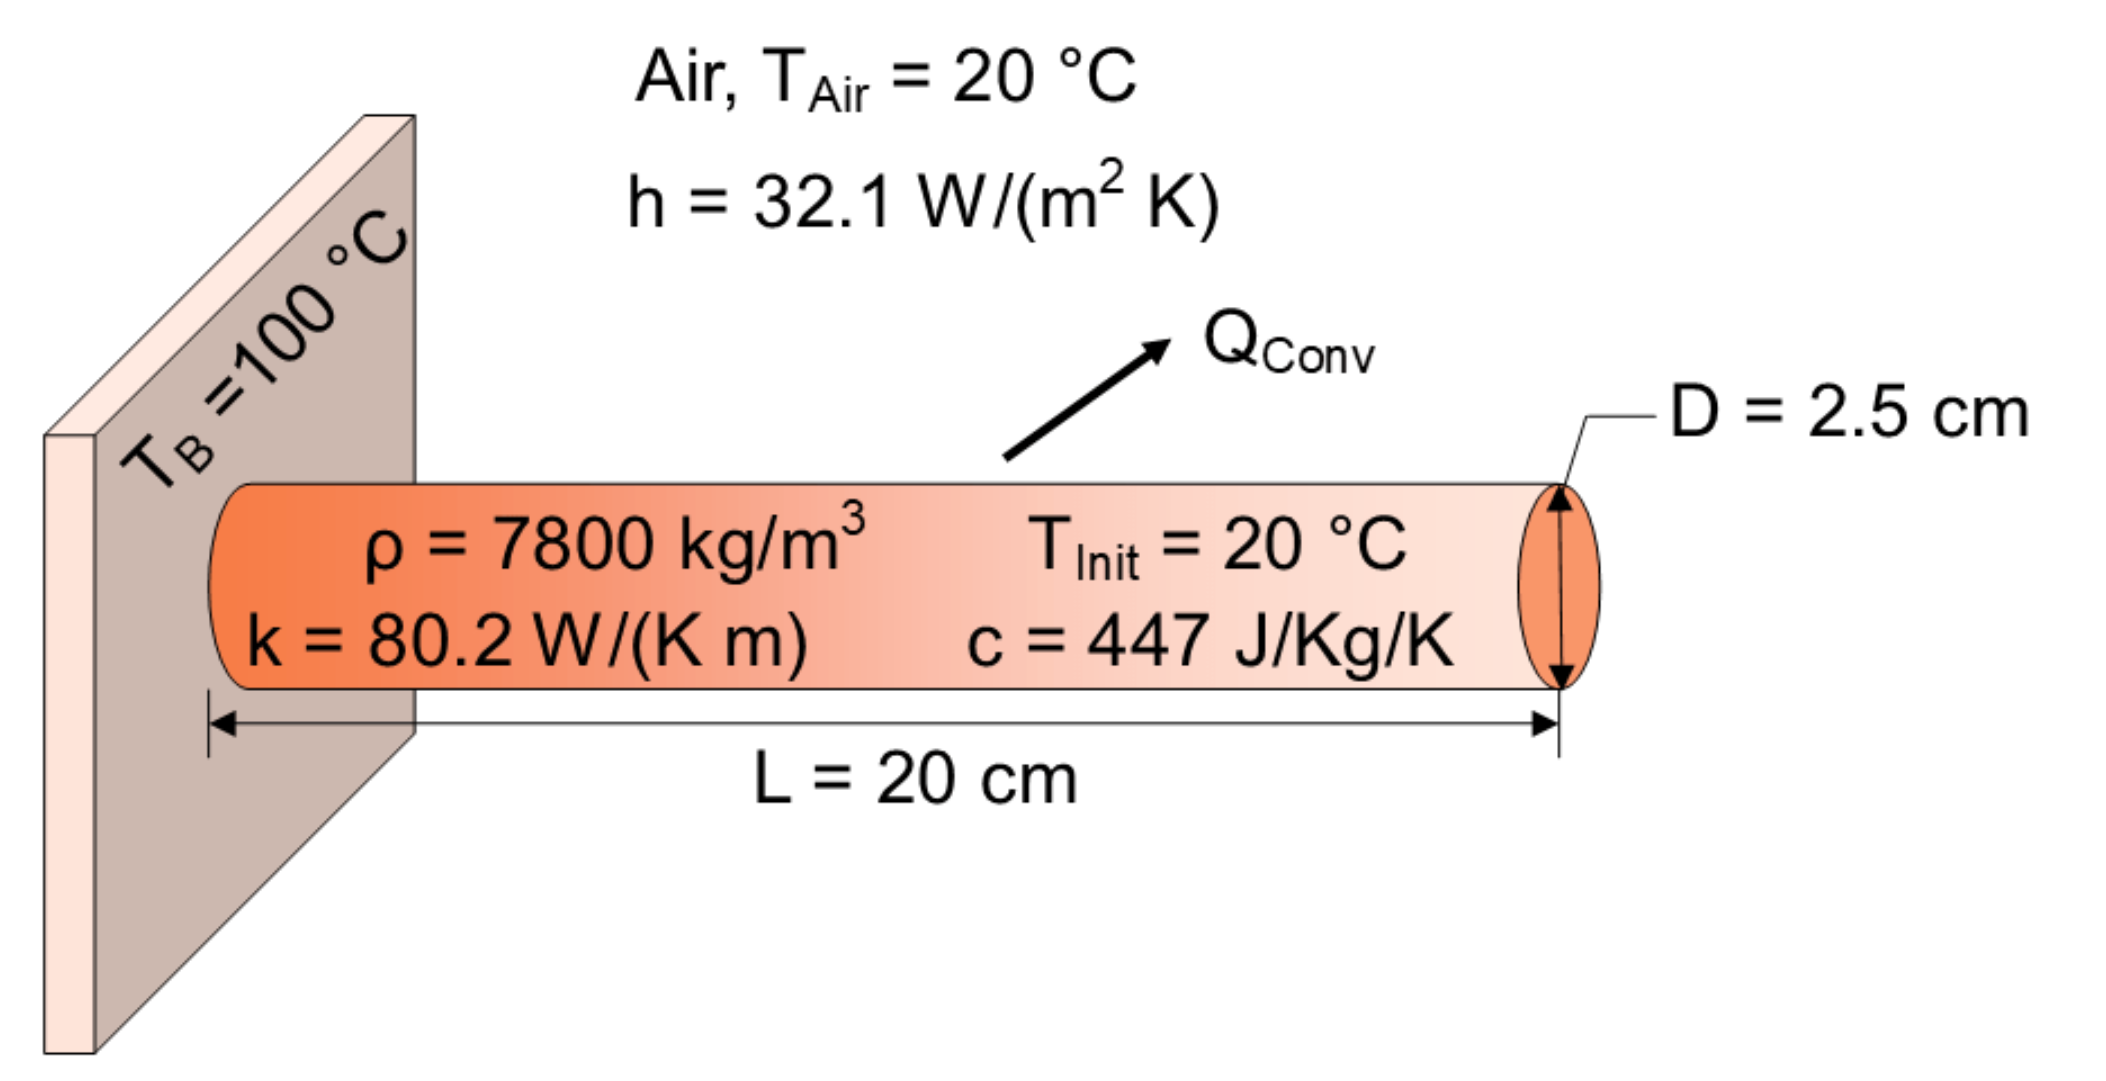

This example form MathWorks documentation uses the canonical example of heat transfer in an iron rod to show conduction and convection in a lumped model. By adding the thermal mass for the rod, you can switch from steady-sate to transient solution. Also, by segmenting the mass to one or multiple parts, one can see the significance of partitioning the physical domain on the simulation results, and find the appropriate use cases for each approach. 

openExample("simscape/HeatConductionThroughIronRodExample",...
    "workDir",strcat(currentFileFolder,"\Iron_Rod"))
 

## House Heating System

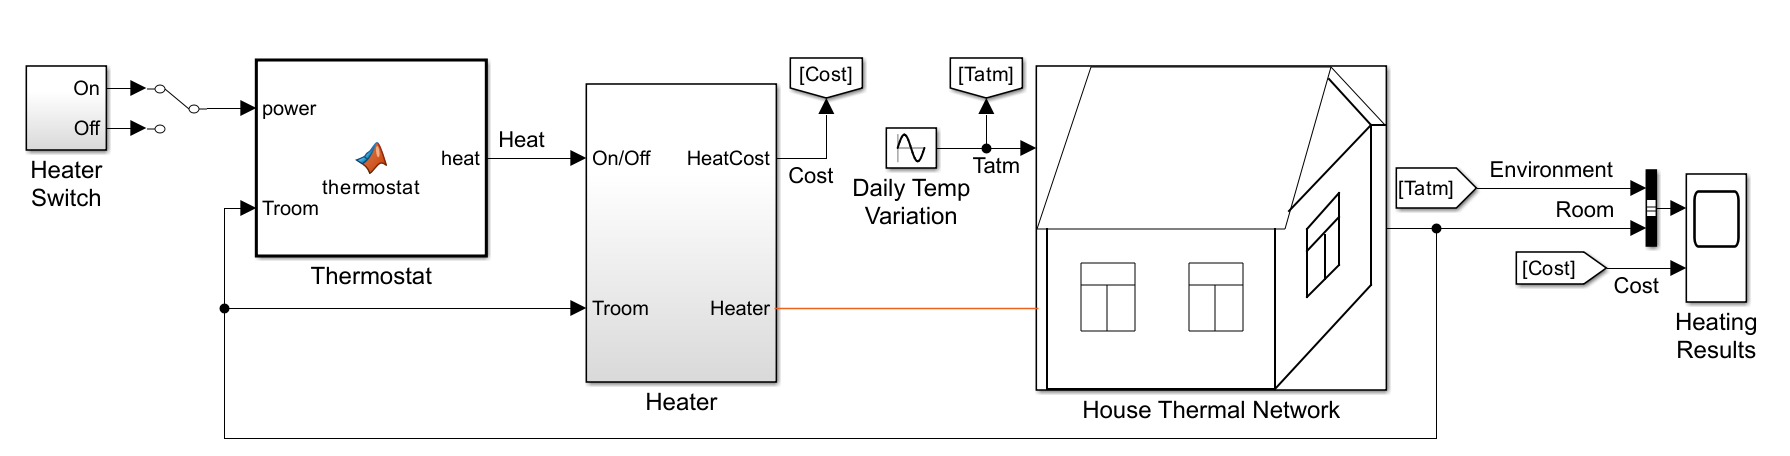

This example put the basics of heat transfer explained in the example above (lumped conduction, convection, and thermal mass) to model a simple thermal network of a house that includes conduction/convection from internal air through roof, wall, and window to external environment. It also include a basic heater and thermostat (with on/off control) model to simulate the thermal behavior in multiple days of operation.

openExample('simscape/HouseHeatingSystemExample',...
    "workDir",strcat(currentFileFolder,"\House_Heating"))
open HouseHeatingSystem.slx
 

For a more complex model (including multiple rooms and radiators, boiler model) check another [House heating system ](https://www.mathworks.com/help/hydro/ug/house-heating-system.html)example.

**Note:** In the house heating examples above, for a typical house on earth, the correct frequency of "Daily Temperature Variation" block is 2*pi/(24*3600) (rad/sec). Please modify it accordingly. 